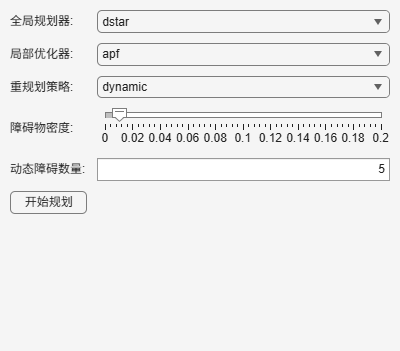

%% 路径规划系统演示
% 基于全局与局部规划器的混合路径规划系统

%% 1. 算法配置（交互式参数设置）
% 创建一个控制面板
fig = uifigure('Name', '路径规划参数配置', 'Position', [100 100 400 350]);
grid = uigridlayout(fig, [6 2]);
grid.RowHeight = {'fit','fit','fit','fit','fit','fit'};
grid.ColumnWidth = {'fit', '1x'};

% 全局规划器选项
uilabel(grid, 'Text', '全局规划器:');
globalDrop = uidropdown(grid, 'Items', {'astar', 'dijkstra', 'dstar', 'rrt'}, 'Value', 'dstar');

% 局部优化器选项
uilabel(grid, 'Text', '局部优化器:');
localDrop = uidropdown(grid, 'Items', {'apf', 'dwa'}, 'Value', 'apf');

% 重规划策略选项
uilabel(grid, 'Text', '重规划策略:');
replanDrop = uidropdown(grid, 'Items', {'dynamic', 'static'}, 'Value', 'dynamic');

% 障碍物密度控制
uilabel(grid, 'Text', '障碍物密度:');
obsSlider = uislider(grid, 'Limits', [0 0.2], 'Value', 0.01);

% 动态障碍物数量
uilabel(grid, 'Text', '动态障碍数量:');
obsNumEdit = uieditfield(grid, 'numeric', 'Value', 5);

% 存储控件的应用数据
appData = struct();
appData.globalDrop = globalDrop;
appData.localDrop = localDrop;
appData.replanDrop = replanDrop;
appData.obsSlider = obsSlider;
appData.obsNumEdit = obsNumEdit;

% 确认按钮 - 正确传递应用数据
uibutton(grid, 'Text', '开始规划', 'ButtonPushedFcn', ...
    @(btn, event) startPlanning(appData));


%% 2. 规划回调函数
function startPlanning(appData)
    % 获取配置参数
    config.global_planner = appData.globalDrop.Value;
    config.local_planner = appData.localDrop.Value;
    config.replan_strategy = appData.replanDrop.Value;
    config.obstacle_density = appData.obsSlider.Value;
    config.new_obstacles_num = appData.obsNumEdit.Value;
    config.map_size = [100, 100];
    config.map_resolution = 4;

    % 关闭配置面板
    delete(appData.globalDrop.Parent.Parent); % 删除整个配置窗口
    
    % 环境初始化
    try
        addpath(genpath('planner'));
        addpath(genpath('utils'));
    catch ME
        errordlg(['路径初始化失败: ' ME.message], '初始化错误');
        return;
    end
    
    % 创建主显示窗口
    mainFig = figure('Name', '路径规划系统', 'Position', [100 100 800 600]);
    t = tiledlayout(mainFig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    %% 第一阶段：环境初始化
    ax1 = nexttile(t, [1, 1]);
    title(ax1, '1. 环境地图与任务点');
    
    % 生成随机地图
    try
        [map, start, goal] = generate_valid_environment(config);
    catch
        errordlg('地图生成失败，请检查参数设置', '地图错误');
        return;
    end
    
    % 显示地图
    imagesc(ax1, map);
    colormap(ax1, [1 1 1; 0 0 0; 1 0.5 0]); % 白色-空闲，黑色-障碍，橙色-动态障碍
    hold(ax1, 'on');
    plot(ax1, start(2), start(1), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    plot(ax1, goal(2), goal(1), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
    legend(ax1, '起点', '终点', 'Location', 'best');
    axis(ax1, 'equal');
    
    %% 第二阶段：路径规划
    ax2 = nexttile(t, [1, 1]);
    title(ax2, '2. 全局路径规划');
    
    % 复制地图显示
    imagesc(ax2, map);
    colormap(ax2, [1 1 1; 0 0 0; 1 0.5 0]);
    hold(ax2, 'on');
    plot(ax2, start(2), start(1), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    plot(ax2, goal(2), goal(1), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
    
    % 全局规划
    try
        global_planner = get_planner(config.global_planner, 'global');
        [global_path1, explored1] = global_planner(map, start, goal);
    catch
        errordlg(['全局规划失败: ' config.global_planner], '规划错误');
        return;
    end
    
    % 显示全局路径
    plot(ax2, global_path1(:,2), global_path1(:,1), 'b-', 'LineWidth', 1.5);
    
    %% 第三阶段：局部优化
    ax3 = nexttile(t, [1, 1]);
    title(ax3, '3. 局部路径优化');
    imagesc(ax3, map);
    colormap(ax3, [1 1 1; 0 0 0; 1 0.5 0]);
    hold(ax3, 'on');
    plot(ax3, start(2), start(1), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    plot(ax3, goal(2), goal(1), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
    plot(ax3, global_path1(:,2), global_path1(:,1), 'b-', 'LineWidth', 1);
    
    % 局部优化
    try
        local_planner = get_planner(config.local_planner, 'local');
        [refined_path1] = local_planner(map, global_path1, goal);
    catch
        errordlg(['局部优化失败: ' config.local_planner], '优化错误');
        return;
    end
    
    % 显示优化路径
    plot(ax3, refined_path1(:,2), refined_path1(:,1), 'g-', 'LineWidth', 2);
    legend(ax3, '起点', '终点', '全局路径', '优化路径', 'Location', 'best');
    
    %% 第四阶段：动态障碍
    ax4 = nexttile(t, [1, 1]);
    title(ax4, '4. 动态障碍检测');
    imagesc(ax4, map);
    colormap(ax4, [1 1 1; 0 0 0; 1 0.5 0]);
    hold(ax4, 'on');
    plot(ax4, start(2), start(1), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    plot(ax4, goal(2), goal(1), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
    plot(ax4, refined_path1(:,2), refined_path1(:,1), 'g-', 'LineWidth', 2);
    
    % 生成随机动态障碍物
    try
        new_obstacles = generate_dynamic_obstacles(map, start, goal, config.new_obstacles_num);
    catch
        errordlg('动态障碍生成失败', '障碍错误');
        return;
    end
    
    % 更新地图并可视化
    for i = 1:size(new_obstacles, 1)
        map(new_obstacles(i,1), new_obstacles(i,2)) = 2;
        plot(ax4, new_obstacles(i,2), new_obstacles(i,1), 's', ...
            'MarkerSize', 8, 'MarkerFaceColor', [1 0.5 0], 'MarkerEdgeColor', 'k');
    end
    
    %% 第五阶段：路径阻断检测
    figure(mainFig); % 切换回主图窗
    
    % 路径阻断检测
    try
        [blocked, new_start, blockage_index] = detect_blockage(refined_path1, new_obstacles, map, config.replan_strategy);
    catch
        errordlg('路径阻断检测失败', '检测错误');
        return;
    end
    
    % 可视化阻断点
    if blocked
        plot(ax4, new_start(2), new_start(1), 'mx', 'MarkerSize', 12, 'LineWidth', 2);
        text(ax4, new_start(2)+1, new_start(1), '阻断点', 'Color', 'm', 'FontSize', 10);
    end
    
    %% 第六阶段：路径重规划
    if blocked
        % 创建新图形区域
        figure; % 新建图窗
        ax5 = axes;
        title(ax5, '5. 路径重规划');
        imagesc(ax5, map);
        colormap(ax5, [1 1 1; 0 0 0; 1 0.5 0]);
        hold(ax5, 'on');
        plot(ax5, goal(2), goal(1), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
        plot(ax5, new_obstacles(:,2), new_obstacles(:,1), 's', ...
            'MarkerSize', 8, 'MarkerFaceColor', [1 0.5 0], 'MarkerEdgeColor', 'k');
        plot(ax5, new_start(2), new_start(1), 'mx', 'MarkerSize', 12, 'LineWidth', 2);
        
        % 全局重规划
        try
            [global_path2, explored2] = global_planner(map, new_start, goal);
        catch
            errordlg('重规划失败', '规划错误');
            return;
        end
        
        % 显示重规划全局路径
        plot(ax5, global_path2(:,2), global_path2(:,1), 'c-', 'LineWidth', 1.5);
        
        % 局部优化
        try
            [replanned_path] = local_planner(map, global_path2, goal);
        catch
            errordlg('重规划局部优化失败', '优化错误');
            return;
        end
        
        % 显示重规划结果
        plot(ax5, replanned_path(:,2), replanned_path(:,1), 'm-', 'LineWidth', 2);
        
        % 路径拼接与显示
        try
            refined_path2 = stitch_paths(refined_path1(1:blockage_index, :), replanned_path);
        catch
            errordlg('路径拼接失败', '拼接错误');
            return;
        end
        
        plot(ax5, refined_path2(:,2), refined_path2(:,1), 'y-', 'LineWidth', 2);
        legend(ax5, '目标点', '动态障碍', '阻断点', '重规划全局', '重规划优化', '最终路径', 'Location', 'best');
    end
    
    %% 第七阶段：结果分析与报告
    figure; % 新建图窗用于报告
    t = tiledlayout(2, 2, 'TileSpacing', 'compact');
    
    % 路径统计
    stats.original_length = calculate_path_length(global_path1);
    stats.smoothed_length = calculate_path_length(refined_path1);
    
    if blocked && exist('refined_path2', 'var')
        stats.replanned_length = calculate_path_length(refined_path2);
        stats.turning_points_original = length(calculate_turning_points(refined_path1));
        stats.turning_points_replanned = length(calculate_turning_points(refined_path2));
    else
        stats.replanned_length = NaN;
        stats.turning_points_original = length(calculate_turning_points(refined_path1));
        stats.turning_points_replanned = NaN;
    end
    
    % 显示统计结果表格
    axStats = nexttile(t);
    delete(axStats); % 删除自动创建的坐标区
    stats_table = table(...
        stats.original_length, stats.smoothed_length, stats.replanned_length, ...
        stats.turning_points_original, stats.turning_points_replanned, ...
        'VariableNames', {'原始长度', '优化长度', '重规划长度', '原始拐点', '重规划拐点'}, ...
        'RowNames', {'路径统计'});
    
    uitable('Data', stats_table.Variables, ...
        'ColumnName', stats_table.Properties.VariableNames, ...
        'RowName', stats_table.Properties.RowNames, ...
        'Parent', t);
    
    % 可视化距离分析
    nexttile(t);
    if exist('refined_path2', 'var')
        visualize_obstacle_distances(map, refined_path1, refined_path2);
    else
        visualize_obstacle_distances(map, refined_path1, []);
    end
    title('障碍物距离分析');
    
    % 可视化拐点分析
    nexttile(t);
    if exist('refined_path2', 'var')
        visualize_turning_points(refined_path1, refined_path2);
    else
        visualize_turning_points(refined_path1, []);
    end
    title('路径拐点分析');
    
    % 最终路径展示
    nexttile(t);
    imagesc(map);
    colormap([1 1 1; 0 0 0; 1 0.5 0]);
    hold on;
    plot(start(2), start(1), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    plot(goal(2), goal(1), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
    
    if exist('refined_path2', 'var')
        plot(refined_path2(:,2), refined_path2(:,1), 'y-', 'LineWidth', 2);
        plot(global_path1(:,2), global_path1(:,1), 'b:', 'LineWidth', 0.5);
        legend('起点', '终点', '最终路径', '原始路径', 'Location', 'best');
    else
        plot(refined_path1(:,2), refined_path1(:,1), 'g-', 'LineWidth', 2);
        legend('起点', '终点', '最终路径', 'Location', 'best');
    end
    title('最终路径');
end